Pn = 37*10^3; % номинальная мощность
nn = 1470; % номинальная частота вращения (об/мин)
kpd = 92/100; % коэффициент полезного действия
cosfi = 0.85; % коэффициент мощности
Un = 380/sqrt(3); % фазное напряжение питания
In = 71.9; % линейный или фазный ток 
Mn = 240; % номинальный момент нагрузки
ks = 2.4; % кратность пускового момента ks =Ms/Mn
ki = 6.7; % кратность пускового тока ki =Is/In
lyambda = 2.5; % кратность максимального момента λ=Mm/Mn

m = 3; % число фаз
f = 50; % частота сети
zp = 2; % число пар полюсов

n1 = 60*f/zp % частота вращения магнитного поля статора(скорость циклического изменения магнитного потока статора, называется синхронной скоростью двигателя)

n1 = 1500

sn = (n1-nn)/n1; % величина номинального скольжения
N = 1500; % синхронная частота вращения (об/мин)
J = 0.27; %
mass = 245; %
service_factor = 1.15; %

% Параметры схемы замещения
w1 = 2*pi*f %скорость вращения поля

w1 = 314.1593

2*pi*f/zp

ans = 157.0796


%------
Rs = (Un*In*cosfi-Mn*w1/m/zp)/In^2

Rs = 0.1628

Rr0 = m*zp*Un^2*sn/w1/Mn

Rr0 = 0.0766

%------

mu_m = @(r2_) mu_m_calc(r2_,Rs,sn,lyambda,In,cosfi,Un,m,zp,w1,Mn);
Rr = fzero(mu_m,Rr0)

Rr = 0.0680


a = Rs/Rr

a = 2.3965

A = 1-2*a*sn*(lyambda-1)

A = 0.8562

s_m = sn*(lyambda+sqrt(lyambda^2-A))/A

s_m = 0.1126

x_ks = sqrt((Rr/s_m)^2-Rs^2)

x_ks = 0.5808

b = x_ks/((Rs+Rr/sn)^2+x_ks^2)

b = 0.0446

x_m = 1/((In*sqrt(1-cosfi^2))/Un-b)

x_m = 7.8121

x_s1 = x_ks/2;
x_s2 = x_ks/2;
I2_ = Un/sqrt((Rs+Rr/s_m)^2+(x_ks+x_m)^2)

I2_ = 26.0320

mu_m = m*zp*I2_^2*Rr/(w1*s_m*Mn)

mu_m = 0.0325


%------
h0 = 3;
mu_s = @(h) mu_s_calc(h,m,zp,Un,Rr,w1,Mn,Rs,x_s1,x_s2,ks);
h = fzero(mu_s,h0)

h = 2.9912


k_r = h*(sinh(2*h)+sin(2*h))/(cosh(2*h)-cos(2*h))

k_r = 3.0011

k_x = 3/2/h*(sinh(2*h)-sin(2*h))/(cosh(2*h)-cos(2*h))

k_x = 0.5047

mu_s = m*zp*Un^2*Rr*k_r/(w1*Mn*((Rs+Rr*k_r)^2+(x_s1+x_s2*k_x)^2))

mu_s = 2.4000

% Электрическая частота
w0_ = 2*pi*f;
w_ = 0.1*w0_:0.1*w0_:w0_;
% Механическая частота
w_mech0 = 2*pi*f/zp;
w_mech = 0.1*w_mech0:0.1*w_mech0:w_mech0;
% Индуктивность обмоток
Ls = (x_s1+x_m) / w0_;
Lr = (x_s2+x_m) / w0_;
Lm = x_m / w0_;
% изменяющиеся индуктивные сопротивления рассеяния 
x_s = Ls * w_;
x_r = Lr * w_;
x_m = Lm * w_;

Ku = Lr/(Ls*Lr - Lm^2);
Ki = (Rs*Lr^2 + Lm^2*Rr)/(Ls*Lr^2 - Lm^2*Lr);
K1 = Lm*Rr/(Ls*Lr^2 - Lm^2*Lr^2);
K2 = Lm/(Ls*Lr - Lm^2);
K3 = Lm*Rr/Lr;
K4 = Rr/Lr;

Mn_flag = 2;
Tmdl = 5;

M_mech_sim = out.mechanic.Data(:,1); 
w_mech_sim = out.mechanic.Data(:,2) * 30/pi;
t = out.mechanic.Time;
Ia = out.electric.Data(:,1);
Ib = out.electric.Data(:,2);

u_a = out.U.Data(:,1);
u_a = [t u_a];
u_b = out.U.Data(:,2);
u_b = [t u_b];
u_c = out.U.Data(:,3);
u_c = [t u_c];

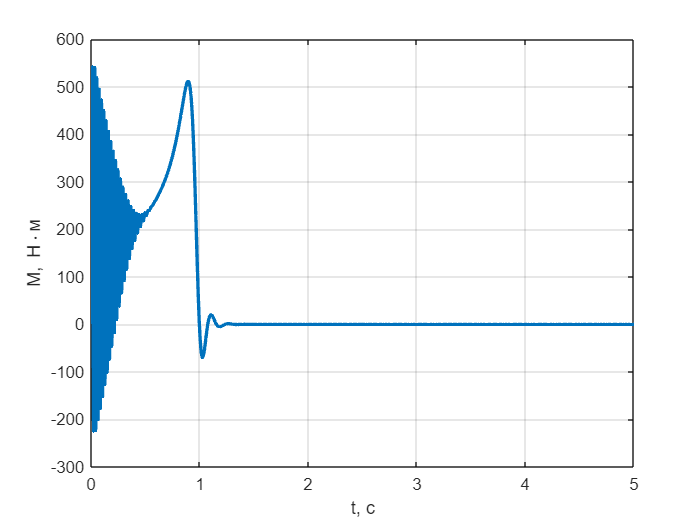

figure()
plot(t, M_mech_sim, 'LineWidth',2);
grid on
xlabel('t, c');
ylabel('M, Н\cdotм');

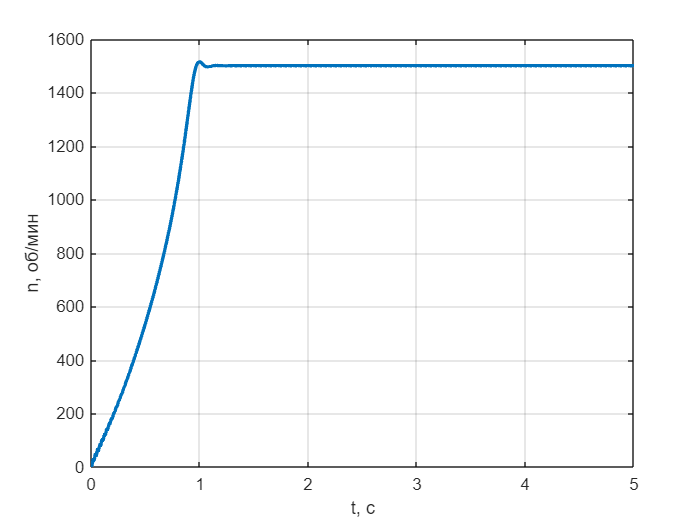

figure()
plot(t, w_mech_sim, 'LineWidth',2);
grid on
xlabel('t, c');
ylabel('n, об/мин');

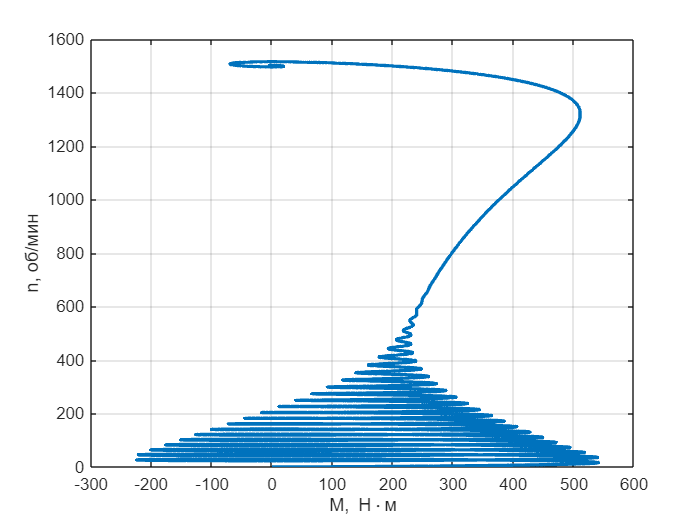

figure()
plot(M_mech_sim,w_mech_sim, 'LineWidth',2);
grid on
xlabel('M, Н\cdotм');
ylabel('n, об/мин');